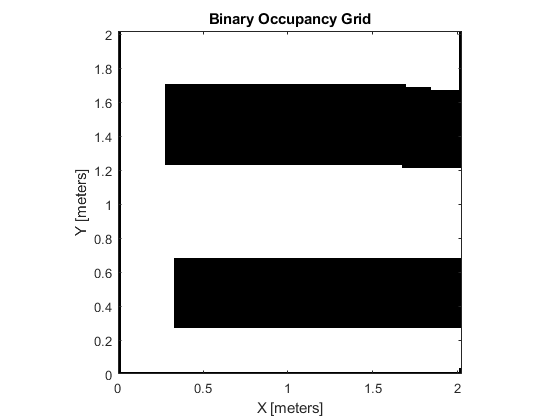

% Load the image
img = imread('C:\Users\frede\OneDrive\Dokumenter\6_semester\ANS\projekt\Testmap1.png');


% Convert the image to grayscale
gray_img = rgb2gray(img);

% Convert the grayscale image to a binary image
binary_img = imbinarize(gray_img);
    
% Create a binary occupancy map from the binary image
scale_factor = 500;   %500 pixels pr. meter
map = binaryOccupancyMap(binary_img,scale_factor);

% Create a new binary occupancy map from the resized matrix
new_map = binaryOccupancyMap(map);

% Show the map
show(new_map);

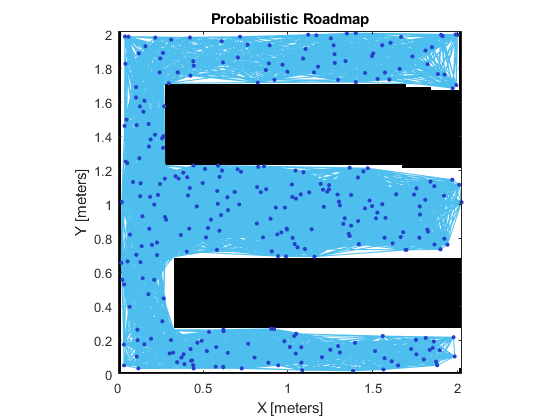

%Create points
NumNodes = 300;
prmComplex = mobileRobotPRM(new_map,NumNodes);
prmComplex.ConnectionDistance = 0.6;
show(prmComplex)

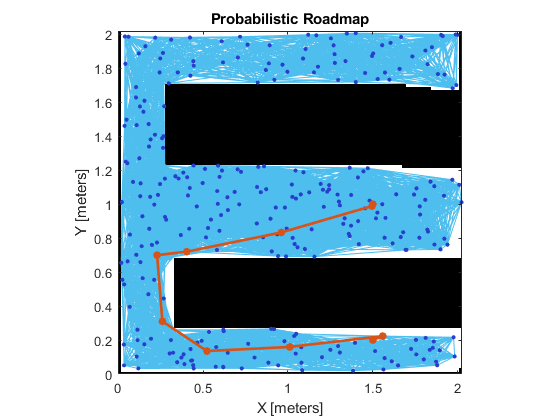

%Define start location
startLocation1 = [1.5 0.2];
endLocation1 = [1.5 1];
path1 = findpath(prmComplex,startLocation1,endLocation1);
show(prmComplex)

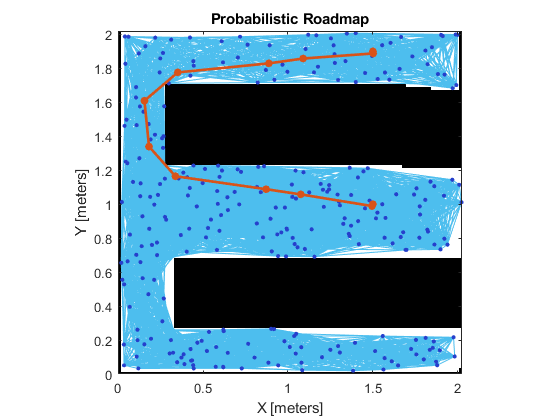


endLocation2 = [1.5 1.9];
path2 = findpath(prmComplex,endLocation1,endLocation2);
show(prmComplex)


robotInitialLocation = path1(1,:)

robotInitialLocation =     1.5000    0.2000


robotGoal = path1(end,:)

robotGoal =     1.5000    1.0000


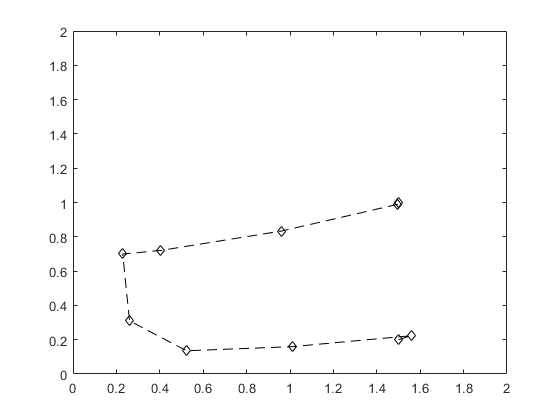


initialOrientation = 0;

robotCurrentPose = [robotInitialLocation initialOrientation]';
robot = differentialDriveKinematics("TrackWidth", 1, "VehicleInputs", "VehicleSpeedHeadingRate");

%1st path
figure
plot(path1(:,1), path1(:,2),'k--d')
xlim([-0 2])
ylim([-0 2])

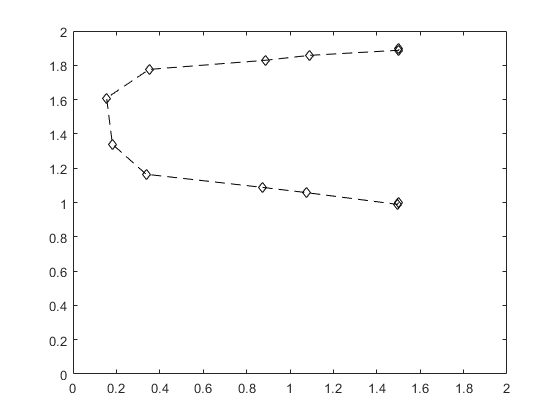


%2nd path
figure
plot(path2(:,1), path2(:,2),'k--d')
xlim([-0 2])
ylim([-0 2])

%Controller 
controller = controllerPurePursuit;
controller.Waypoints = path;
controller.DesiredLinearVelocity = 0.4;
controller.MaxAngularVelocity = 1;
controller.LookaheadDistance = 0.5;

goalRadius = 0.2;
distanceToGoal = norm(robotInitialLocation - robotGoal);

%   
% TIL TURTLEBOT - DEFINITIVT!
vel_pub = rospublisher('/cmd_vel');

The global ROS node is not initialized. Use "rosinit" to start the global node and connect to a ROS network.

velmsg = rosmessage(vel_pub);
odomSub = rossubscriber("/odom","DataFormat","struct");

% Initialize the simulation loop
sampleTime = 0.1;
vizRate = rateControl(1/sampleTime);

% Initialize the figure
figure

% Determine vehicle frame size to most closely represent vehicle with plotTransforms
frameSize = robot.TrackWidth/0.8;
s = path1(1,:)
current_pose = robotCurrentPose

r_pose = receive(odomSub);

init_position = [r_pose.pose.pose.position.x r_pose.pose.pose.position.y]
r_init_orientation = [r_pose.pose.pose.orientation.x r_pose.pose.pose.orientation.y r_pose.pose.pose.orientation.z r_pose.pose.pose.orientation.w]

eul = quat2eul(r_init_orientation);
init_orientation = eul(3);
init_pose = [init_position init_orientation]';

theta = eul(3);
rot_mat = [cosd(theta) -sind(theta); sind(theta) cosd(theta)];

while( distanceToGoal > goalRadius )
    
    % Compute the controller outputs, i.e., the inputs to the robot
    [v, omega] = controller(robotCurrentPose);
    velmsg.Angular.Z = omega;	% Angular velocity (rad/s)
    velmsg.Linear.X = v;
    send(vel_pub,velmsg);

    
    % Get the robot's velocity using controller inputs
    r_pose = receive(odomSub);
    position_x = r_pose.pose.pose.position.x;
    position_y = r_pose.pose.pose.position.y;
    position = [position_x position_y];
    x = r_pose.pose.pose.orientation.x;
    y = r_pose.pose.pose.orientation.y;
    z = r_pose.pose.pose.orientation.z;
    w = r_pose.pose.pose.orientation.w;
    eul = quat2eul([x y z w]);
    orientation = eul(3);
    
    
    robotCurrentPose = [position orientation]' - init_pose;
    %vel = derivative(robot, robotCurrentPose, [v omega]);
    
    % Update the current pose
    %robotCurrentPose = robotCurrentPose + vel*sampleTime; 
    s(end+1,:) = robotCurrentPose(1:2);
    % Re-compute the distance to the goal
    distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:));
    
    % Update the plot
    hold off
    
    % Plot path each instance so that it stays persistent while robot mesh
    % moves
  
    plot(path1(:,1), path1(:,2),"k--d")
    hold all
    
    % Plot the path of the robot as a set of transforms
    plotTrVec = [robotCurrentPose(1:2); 0];
    plotRot = axang2quat([0 0 1 robotCurrentPose(3)]);
    plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", frameSize);
    light;
    xlim([0 2])
    ylim([0 2])
    
    waitfor(vizRate);
end
